## power curve

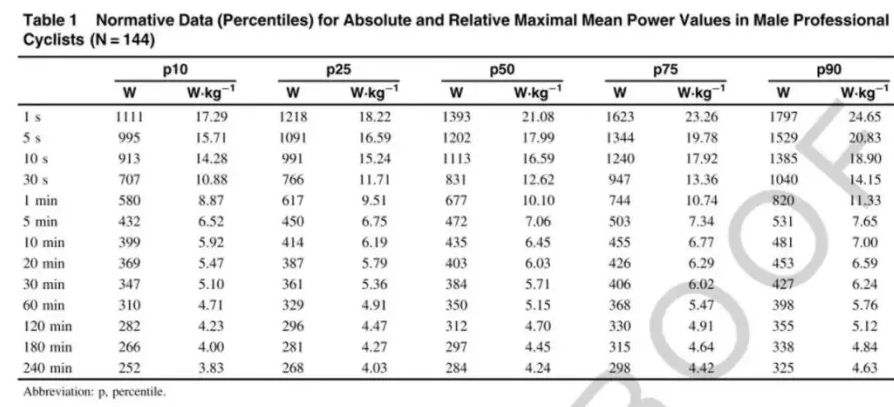

[23.26 19.78 17.92 13.36 10.74 7.34 6.77 6.29 6.02 5.47 4.91 4.64 4.42];

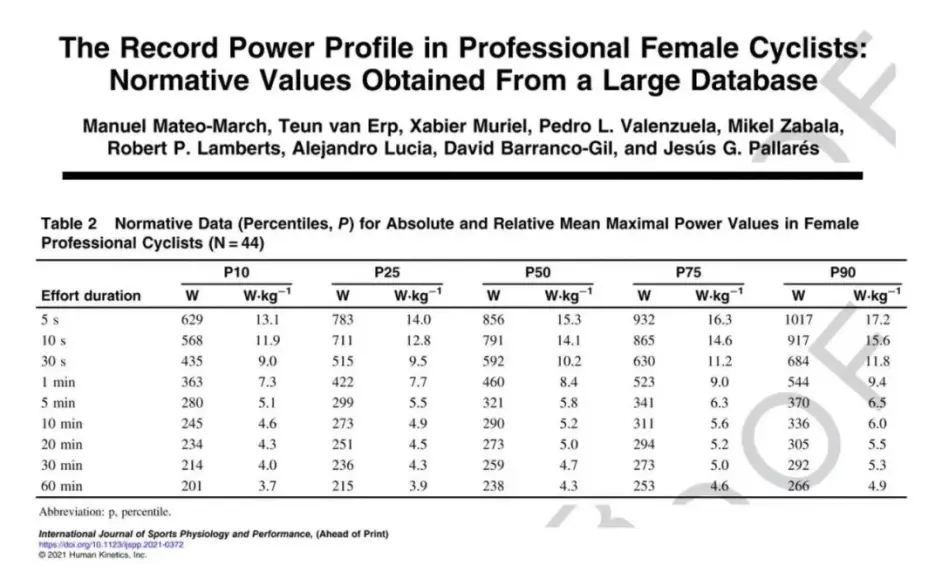

mmt.z1=[1 5 10 30 60 300 600 1200 1800 3600 7200 10800 14400];
Wpm.z1=[24.65 20.84 18.90 14.15 11.33 7.65 7.00 6.59 6.24 5.76 5.12 4.84 4.63];
% maximum 1740
mmt.z2=[5 10 30 60 300 600 1200 1800 3600];
Wpm.z2=[17.2 15.6 11.8 9.4 6.5 6.0 5.5 5.3 4.9];
wei.z1=73;
wei.z2=0.95*wei.z1;
gp.z1=Wpm.z1*wei.z1;
gp.z2=Wpm.z2*wei.z2;
n = 9 ;
[p.z1]=polyfit(mmt.z1,gp.z1,n);

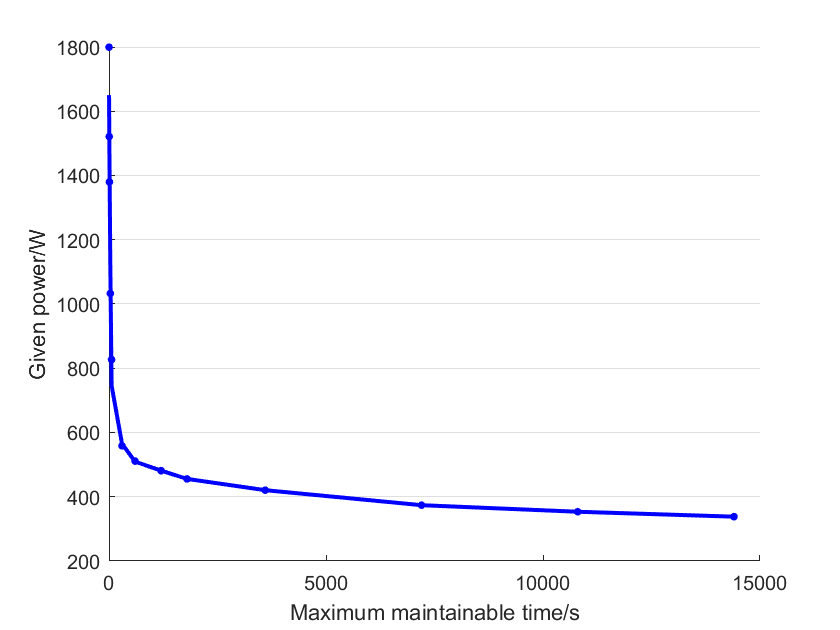

y.z1=polyval(p.z1,mmt.z1);

figure;hold on
plot(mmt.z1,y.z1,'b','LineWidth',2)
scatter(mmt.z1,gp.z1,15,'b','filled');
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
set(gca,'ygrid','on')% 显示y轴网格线


figure
[p.z2]=polyfit(mmt.z2,gp.z2,n);

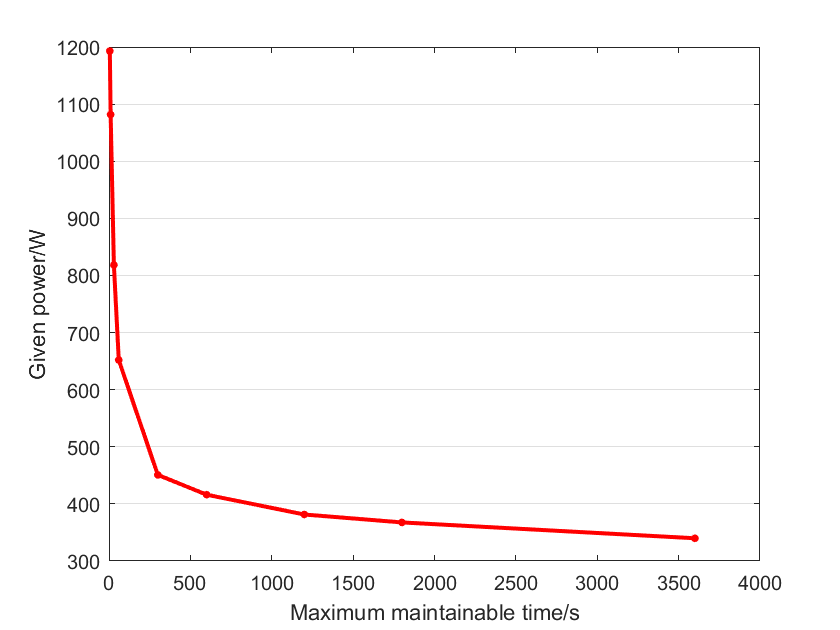

y2=polyval(p.z2,mmt.z2);
plot(mmt.z2,y2,'r','LineWidth',2);hold on% 换一种拟合
scatter(mmt.z2,gp.z2,15,'r','filled');
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
set(gca,'ygrid','on')% 显示y轴网格线

Wpm.p75 = [23.26 19.78 17.92 13.36 10.74 7.34 6.77 6.29 6.02 5.47 4.91 4.64 4.42];
% papo运动员:专门从事比赛的骑手，比赛包括许多短而陡的攀登或许多急剧的加速。
Wpm.p=Wpm.z1.*linspace(1.05,0.9,13);
wei.p=wei.z1*1.01;  % ?????????????????????????????????
gp.p=Wpm.p*wei.p;
1./(gp.p./gp.z1);
mmt.p=mmt.z1*1;
n = 9 ;hold on;

[p.p]=polyfit(mmt.p,gp.p,n);

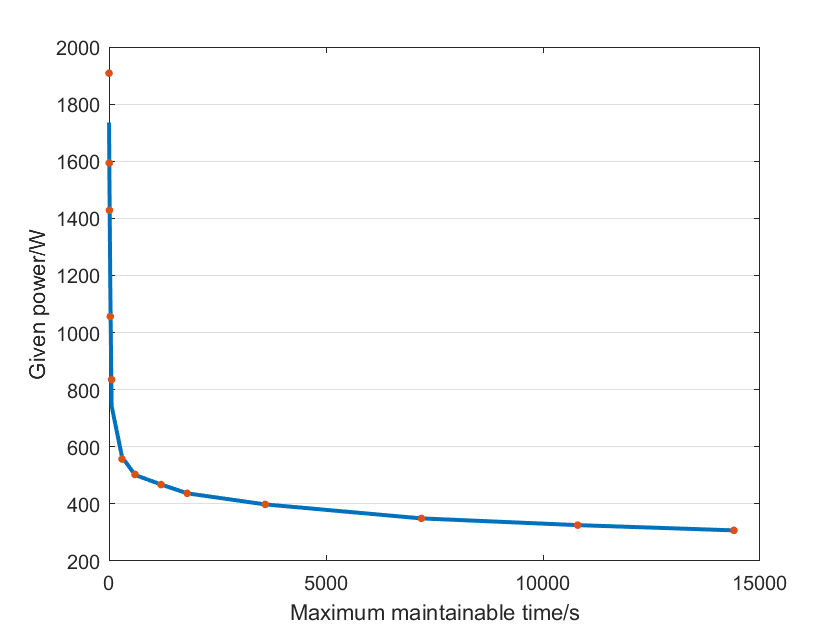

y.p=polyval(p.p,mmt.p);
figure
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
plot(mmt.p,y.p,'LineWidth',2);hold on
scatter(mmt.p,gp.p,15,'filled');
set(gca,'ygrid','on')   % 显示y轴网格线
xlabel('Maximum maintainable time/s');ylabel('Given power/W')

## 攀登者:专门从事多次长距离攀登比赛的骑手。


Wpm.c=Wpm.z1.*linspace(0.85,1.15,13);
wei.c=wei.z1*1.01;  % ?????????????????????????????????
gp.c=Wpm.c*wei.c;
1./(gp.c./gp.z1);
mmt.c=mmt.z1*1;
n = 9 ;hold on;

[p.c]=polyfit(mmt.c,gp.c,n);

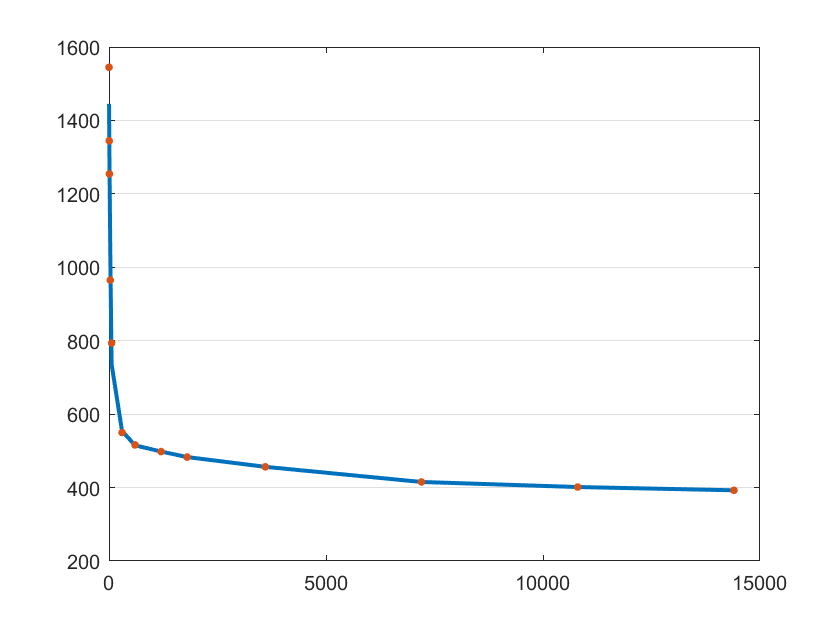

y.c=polyval(p.c,mmt.c);
figure
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
plot(mmt.c,y.c,'LineWidth',2);hold on
scatter(mmt.c,gp.c,15,'filled');
set(gca,'ygrid','on')   % 显示y轴网格线

## 鲁勒尔:多面手，能在各种地形的比赛中表现出色。


% Rouleur: a rider that is a generalist and can do well in races with a wide variety of terrains.
Wpm.d=[23.26 19.78 17.92 13.36 10.74 7.34 6.77 6.29 6.02 5.47 4.91 4.64 4.42];
wei.d=wei.z1*1;  % ?????????????????????????????????
gp.d=Wpm.d*wei.d;
1./(gp.d./gp.z1);
mmt.d=mmt.z1*1;
n = 9 ;hold on;

[p.d]=polyfit(mmt.d,gp.d,n);

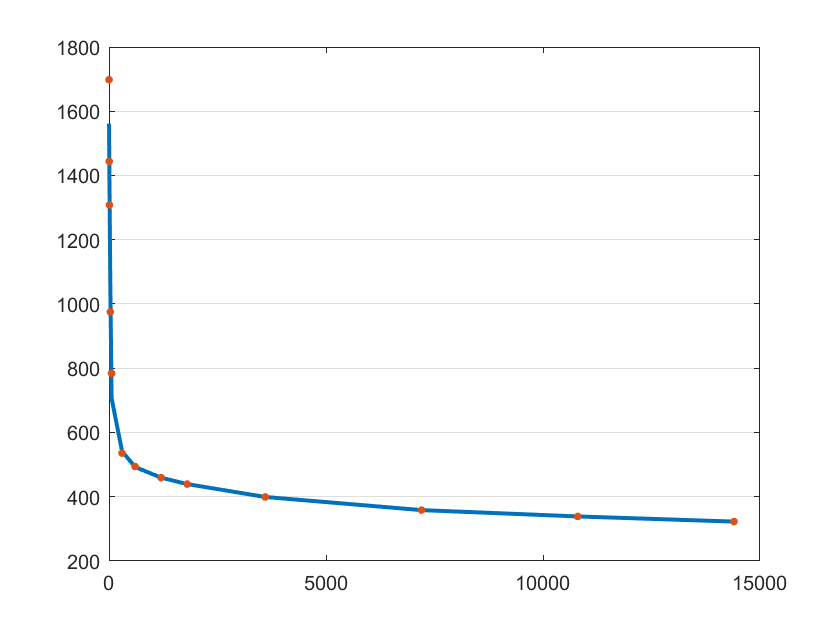

y.d=polyval(p.d,mmt.d);
figure
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
plot(mmt.d,y.d,'LineWidth',2);hold on
scatter(mmt.d,gp.d,15,'filled');
set(gca,'ygrid','on')   % 显示y轴网格线

## 短跑运动员


% 专门在短时间内产生极高力量的骑手。
% 这些骑手通常专注于在比赛结束时或中间冲刺阶段(如果比赛有中间冲刺阶段)获胜。
Wpm.r=Wpm.z1.*linspace(1.4,0.8,13);
wei.r=wei.z1*1;  % ?????????????????????????????????
gp.r=Wpm.r*wei.r;
1./(gp.r./gp.z1);
mmt.r=mmt.z1*1;
n = 9 ;hold on;

[p.r]=polyfit(mmt.r,gp.r,n);

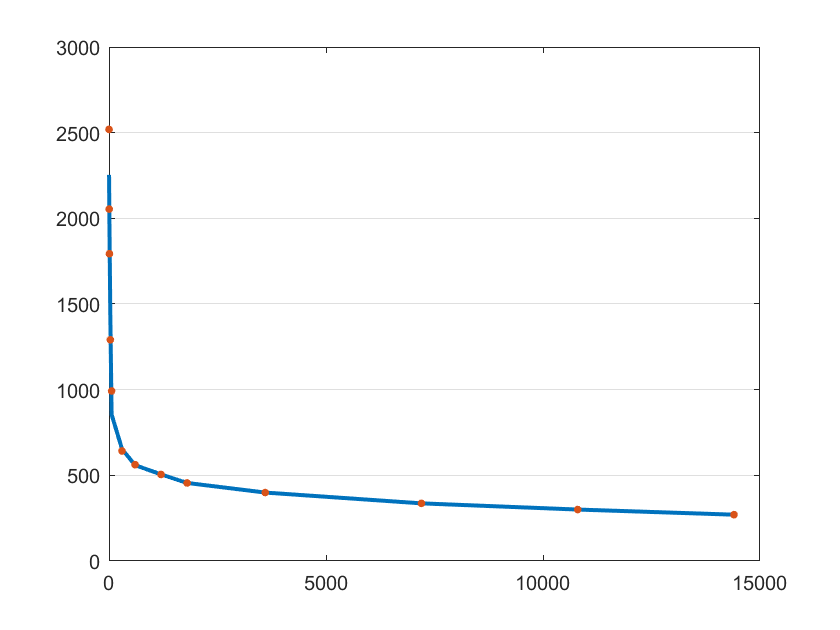

y.r=polyval(p.r,mmt.r);
figure
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
plot(mmt.r,y.r,'LineWidth',2);hold on
scatter(mmt.r,gp.r,15,'filled');
set(gca,'ygrid','on')

## 职业环法选手(前几名的，世界顶尖水平）骑自行车，每赛段160公里，平均输出功率在6W/kg左右，

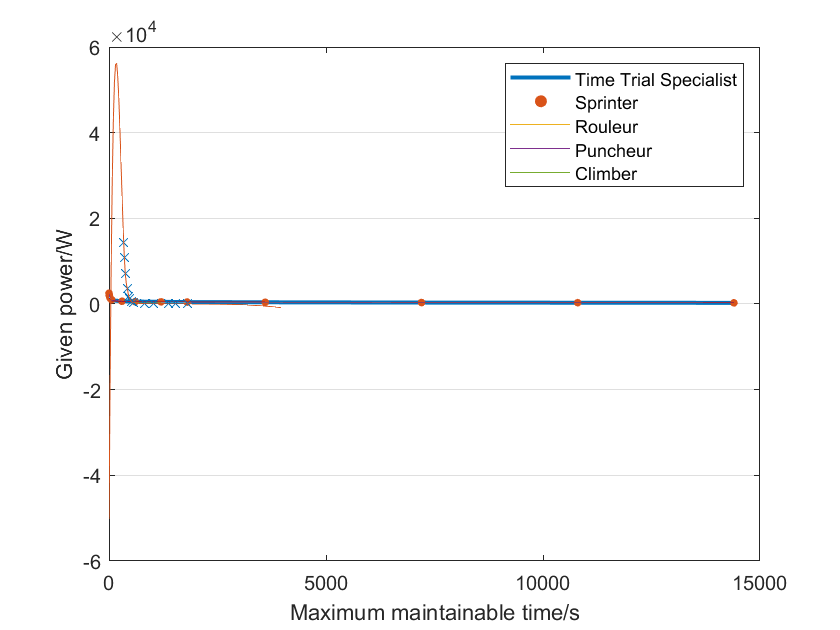


% 再假设选手体重65kg，390W的平均输出功率已经是国际顶尖水平。不过冲刺爆发应该有1700+
%
plot(mmt.z1,y.z1,'LineWidth',0.5);hold on
plot(mmt.r,y.r);hold on
plot(mmt.d,y.d);hold on
plot(mmt.p,y.p);hold on
plot(mmt.c,y.c);hold on

x0 = gp.z1;
y0 = mmt.z1;% 已知数据
xx = 1:25:4000; %插值点
yy = spline(x0,y0,xx); %三次样条插值
plot(x0,y0,'x',xx,yy)
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
legend('Time Trial Specialist','Sprinter','Rouleur','Puncheur','Climber')

## Modeling